clc;clear;

T = 0.5; % loop time
px = 0.2;
py = 0.3;
vx = 0;
vy = 0;
initialState = [px,py,vx,vy]';

% state transition model
F = [1 0 T 0;
     0 1 0 T;
     0 0 1 0;
     0 0 0 1];

% measurement model
M = [1 0 0 0;
     0 1 0 0];

KF = trackingKF(F,M,'State',initialState);
KF.ControlModel = [];

properties(KF);

Properties for class trackingKF:

    MotionModel
    StateTransitionModel
    MeasurementModel
    ControlModel
    State
    StateCovariance
    ProcessNoise
    MeasurementNoise



Create the measured positions from a constant-velocity trajectory.

vx = 0.2;
vy = 0.1;
u = [0 0]';
pos = [0:vx*T:2;0:vy*T:1]';

Predict and correct the state of the object.

for k = 1:size(pos,1)
    pstates(k,:) = predict(KF,u,T);
    cstates(k,:) = correct(KF,pos(k,:));
end

Error using matlabshared.tracking.internal.KalmanFilter/parseInputsToPredict (line 674)
The dimensions of the StateTransitionModel property must not change after the object is constructed.

Error in matlabshared.tracking.internal.KalmanFilter/predict (<a hre

Plot the tracks.

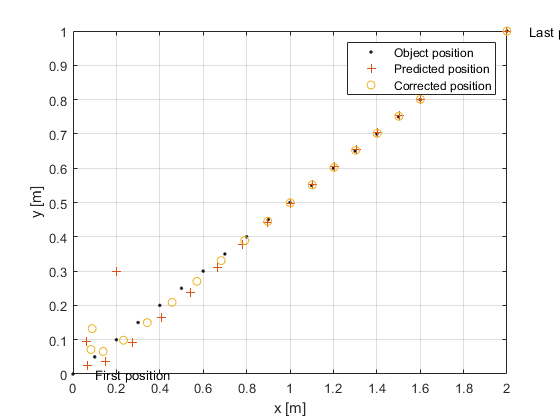

plot(pos(:,1),pos(:,2),'k.', pstates(:,1),pstates(:,3),'+', ...
    cstates(:,1),cstates(:,3),'o')
xlabel('x [m]')
ylabel('y [m]')
grid
xt  = [x-2 pos(1,1)+0.1 pos(end,1)+0.1];
yt = [y pos(1,2) pos(end,2)];
text(xt,yt,{'First measurement','First position','Last position'})
legend('Object position', 'Predicted position', 'Corrected position')

*Copyright 2012 The MathWorks, Inc.*